读取数据

% 从excel里面读取数据
filename = '../data/附件一：已结束项目任务数据.xls';
cNode = 835;  % 送货节点数量（不包括快递公司）

% 读取客户的坐标和需求量
data = readmatrix(filename, 'Range', sprintf('B2:E%d', cNode+1));  % 读取30行数据
y = data(:, 1);
x = data(:, 2);
price = data(:, 3);
isDone = data(:, 4);

画整体热力图

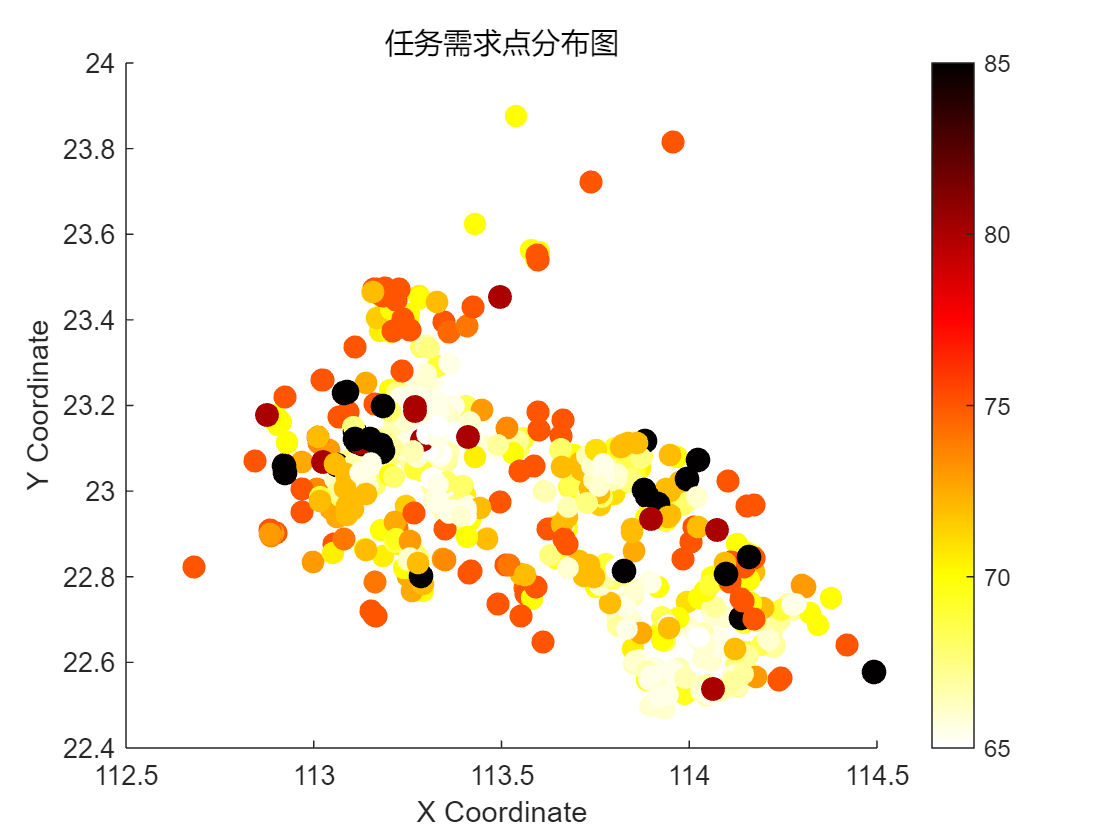

% 绘制散点图，点的大小与需求（price）成正比，颜色与需求成比例
scatter(x, y, price, price, 'filled')
% 添加颜色条，以便参照需求值的颜色变化
colorbar;
colormap(flipud(hot)); % 反转 'hot' 颜色图 % 您可以更改颜色图，如 'jet', 'hsv', 'hot' 等
% 添加标题和标签
title('任务需求点分布图')
xlabel('X Coordinate')
ylabel('Y Coordinate')

只画已完成的点

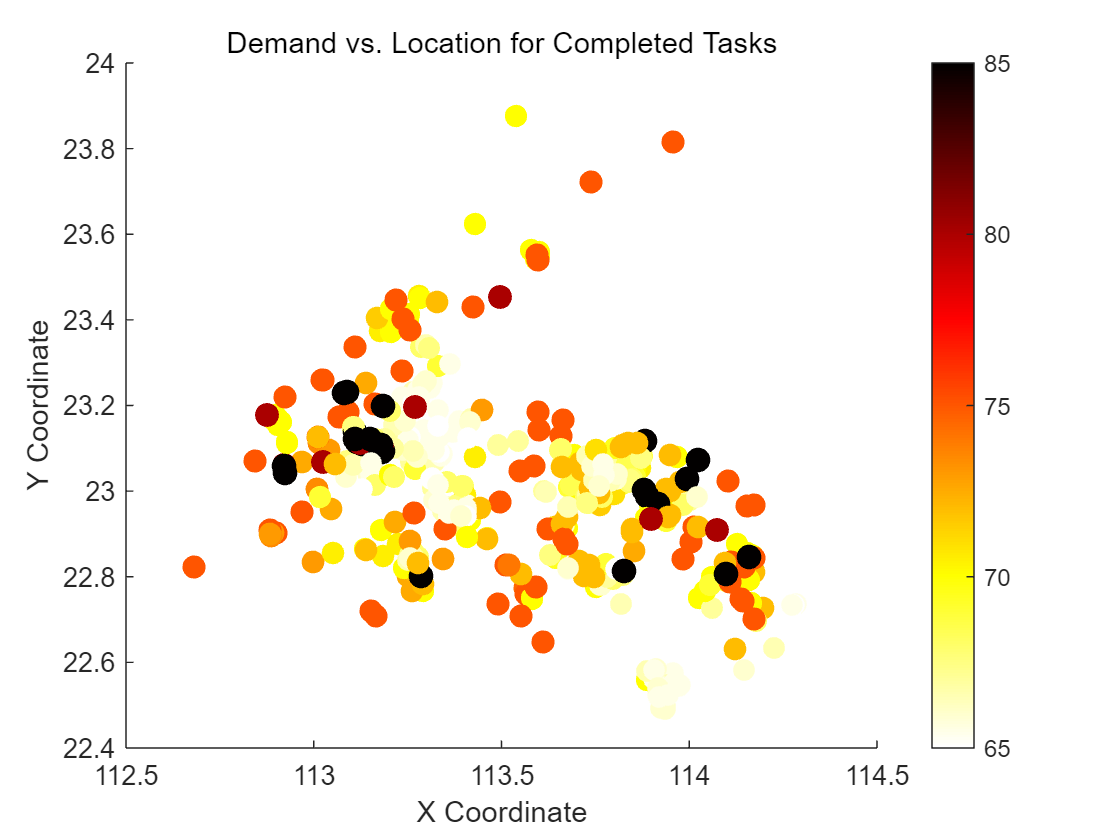

% 筛选出已完成的任务（isDone == 1）
completedIndices = isDone == 1;
xCompleted = x(completedIndices);
yCompleted = y(completedIndices);
priceCompleted = price(completedIndices);

% 绘制散点图，点的大小与需求（price）成正比，颜色与需求成比例
scatter(xCompleted, yCompleted, priceCompleted, priceCompleted, 'filled')

% 反转颜色图并添加颜色条
colormap(flipud(hot)); % 反转 'hot' 颜色图
colorbar;

% 添加标题和标签
title('Demand vs. Location for Completed Tasks')
xlabel('X Coordinate')
ylabel('Y Coordinate')

只画未完成的点

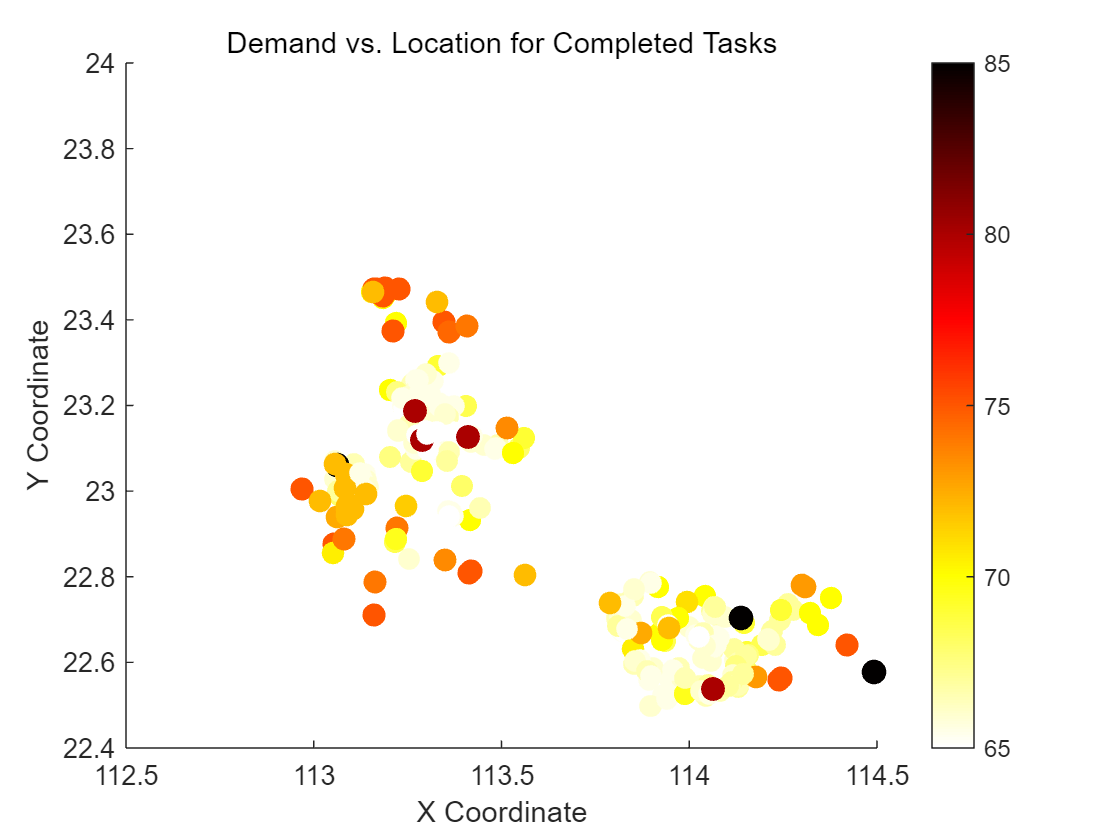

% 筛选出已完成的任务（isDone == 0）
uncompletedIndices = isDone == 0;
xCompleted = x(uncompletedIndices);
yCompleted = y(uncompletedIndices);
priceCompleted = price(uncompletedIndices);

% 绘制散点图，点的大小与需求（price）成正比，颜色与需求成比例
scatter(xCompleted, yCompleted, priceCompleted, priceCompleted, 'filled')

% 反转颜色图并添加颜色条
colormap(flipud(hot)); % 反转 'hot' 颜色图
colorbar;
% 设置横轴和纵轴的显示范围
xlim([112.5 114.5]) % 可以替换为具体范围，如 [110 115]
ylim([22.4 24]) % 可以替换为具体范围，如 [20 25]
% 添加标题和标签
title('Demand vs. Location for Completed Tasks')
xlabel('X Coordinate')
ylabel('Y Coordinate')

已完成的点绿色，未完成的点灰色

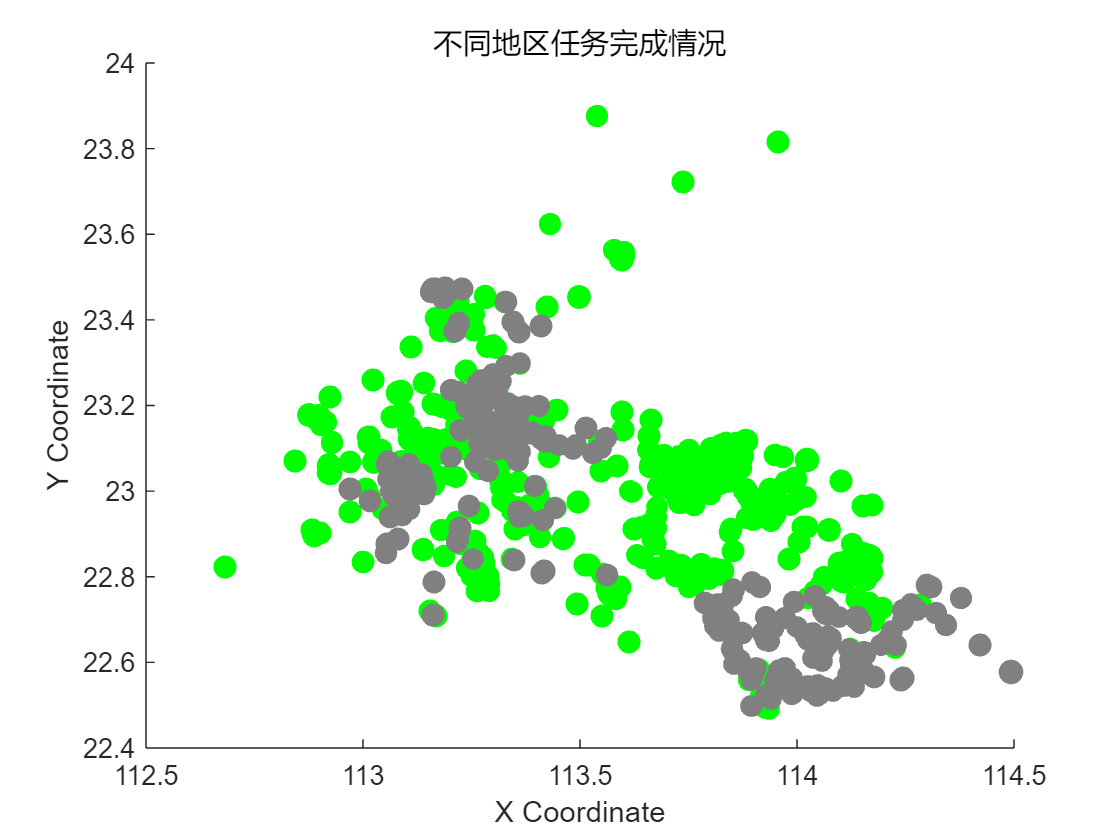

% 筛选出已完成的任务（isDone == 1）和未完成的任务（isDone == 0）
completedIndices = isDone == 1;
incompleteIndices = isDone == 0;

% 已完成任务的坐标和需求
xCompleted = x(completedIndices);
yCompleted = y(completedIndices);
priceCompleted = price(completedIndices);

% 未完成任务的坐标和需求
xIncomplete = x(incompleteIndices);
yIncomplete = y(incompleteIndices);
priceIncomplete = price(incompleteIndices);

% 绘制已完成任务的散点图，点的大小与需求（price）成正比，颜色为绿色
scatter(xCompleted, yCompleted, priceCompleted, 'g', 'filled')
hold on; % 保持当前图形，继续绘制未完成任务

% 绘制未完成任务的散点图，点的大小与需求（price）成正比，颜色为灰色
scatter(xIncomplete, yIncomplete, priceIncomplete, [0.5 0.5 0.5], 'filled')

% 设置横轴和纵轴的显示范围
xlim([112.5 114.5]) % 可以替换为具体范围，如 [110 115]
ylim([22.4 24]) % 可以替换为具体范围，如 [20 25]

% 添加标题和标签
title('不同地区任务完成情况')
xlabel('X Coordinate')
ylabel('Y Coordinate')

% 取消保持
hold off;

统计完成情况

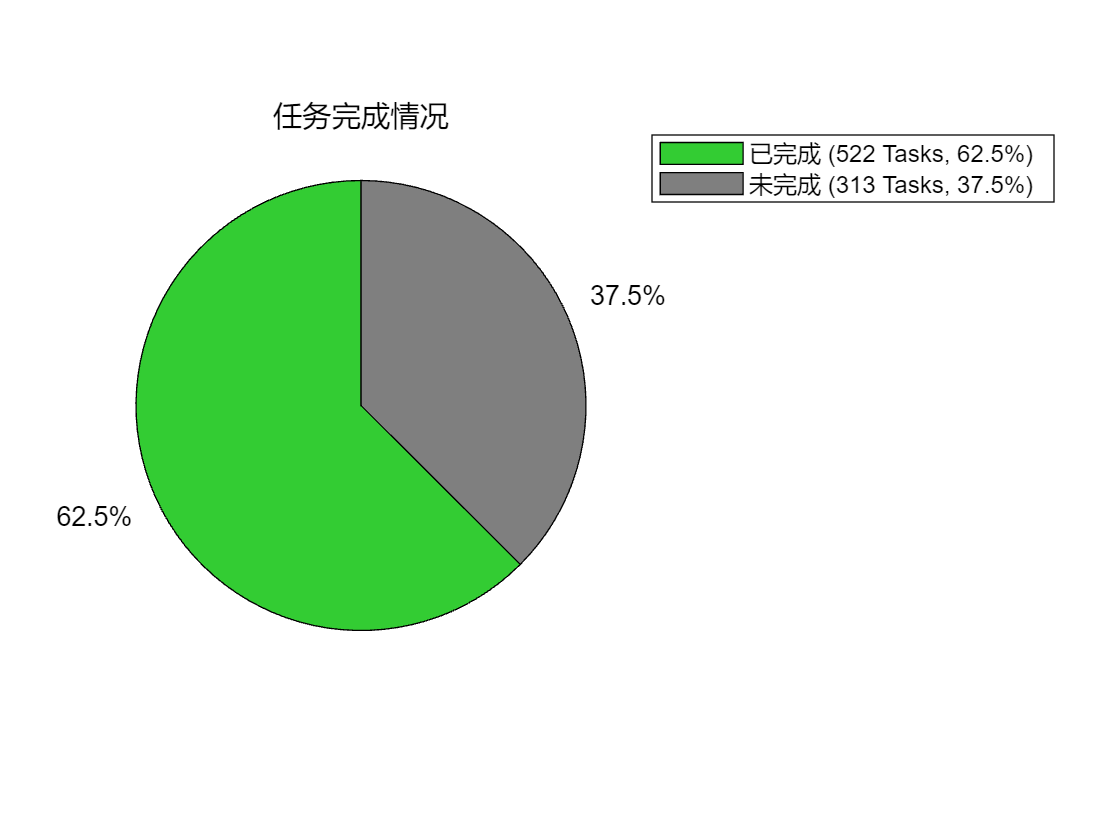

% 筛选出已完成的任务（isDone == 1）和未完成的任务（isDone == 0）
completedCount = sum(isDone == 1);
incompleteCount = sum(isDone == 0);

% 统计结果
taskStatusCounts = [completedCount, incompleteCount];
taskStatusLabels = {'已完成', '未完成'};

% 手动计算百分比
percentages = (taskStatusCounts / sum(taskStatusCounts)) * 100;

% 设置颜色：绿色表示已完成，灰色表示未完成
colors = [0.2 0.8 0.2; 0.5 0.5 0.5]; % 绿色和灰色

% 绘制饼状图
figure; % 创建新图形窗口
p = pie(taskStatusCounts);

% 设置颜色
colormap(colors);

% 手动设置饼图标签为保留一位小数的百分比
for i = 1:2:length(p)
    p(i+1).String = sprintf('%.1f%%', percentages((i+1)/2));  % 使用手动计算的百分比
end

% 创建包含任务数量和百分比的图例标签，确保保留小数点后一位
percentLabels = cellfun(@(label, count, percentage) ...
    sprintf('%s (%d Tasks, %.1f%%)', label, count, percentage), ...
    taskStatusLabels, num2cell(taskStatusCounts), num2cell(percentages), 'UniformOutput', false);

% 添加图例，显示格式与饼图标签一致
legend(p(1:2:end), percentLabels, 'Location', 'bestoutside'); % 图例显示在图外最佳位置

% 添加标题
title('任务完成情况')

计算不同城市

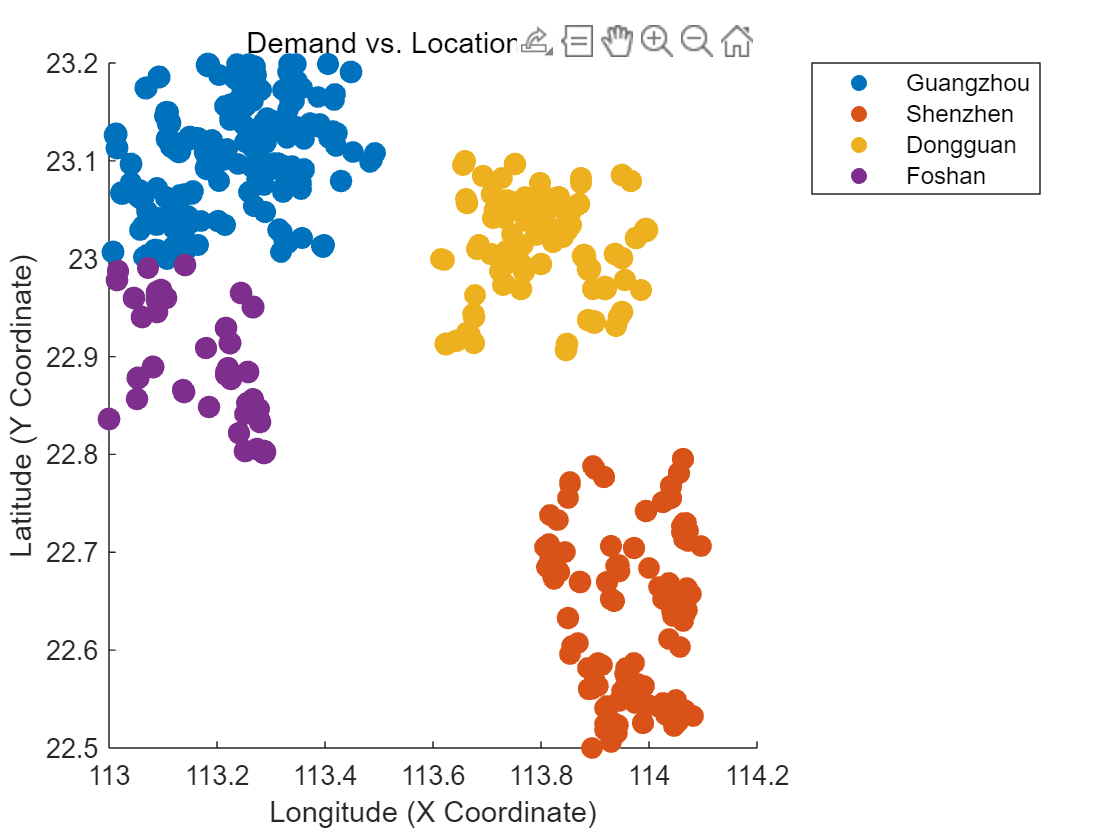

% 定义珠三角主要城市的经纬度范围（这里是示例范围，需要根据实际数据调整）
cities = {'Guangzhou', 'Shenzhen', 'Dongguan', 'Foshan'};
latRange = [23.0 23.2; 22.5 22.8; 22.9 23.1; 22.8 23.0]; % 纬度范围
lonRange = [113.0 113.5; 113.8 114.1; 113.6 114.0; 113.0 113.3]; % 经度范围
cityColors = lines(length(cities)); % 使用不同颜色标识不同城市

% 初始化一个城市索引数组
cityIndex = zeros(size(x));

% 根据经纬度判断所属城市
for i = 1:length(cities)
    inCity = (y >= latRange(i,1) & y <= latRange(i,2)) & (x >= lonRange(i,1) & x <= lonRange(i,2));
    cityIndex(inCity) = i; % 将城市的索引赋值给对应的点
end

% 绘制散点图，根据城市不同分配颜色
figure;
hold on;
for i = 1:length(cities)
    scatter(x(cityIndex == i), y(cityIndex == i), price(cityIndex == i), cityColors(i,:), 'filled');
end
hold off;

% 添加颜色图例
legend(cities, 'Location', 'bestoutside');

% 添加标题和标签
title('Demand vs. Location by City')
xlabel('Longitude (X Coordinate)')
ylabel('Latitude (Y Coordinate)')